% w3 = tf([9 2], [1 6 1],'InputDelay', 1.5)
w4 = tf([8 4 2.4], [10 -5 11], 'InputDelay', 0)

w4 =
 
  8 s^2 + 4 s + 2.4
  -----------------
  10 s^2 - 5 s + 11
 
Continuous-time transfer function.



Wopen = w4

Wopen =
 
  8 s^2 + 4 s + 2.4
  -----------------
  10 s^2 - 5 s + 11
 
Continuous-time transfer function.



Wclose = feedback(Wopen, 1)

Wclose =
 
  8 s^2 + 4 s + 2.4
  -----------------
  18 s^2 - s + 13.4
 
Continuous-time transfer function.



pole(Wopen)

ans =    0.2500 + 1.0186i
   0.2500 - 1.0186i


pole(pade(Wclose))

ans =    0.0278 + 0.8624i
   0.0278 - 0.8624i


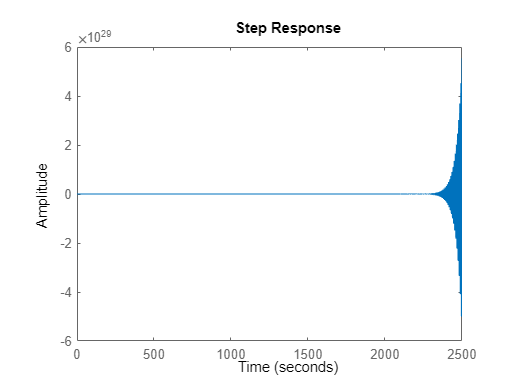

step(Wclose)

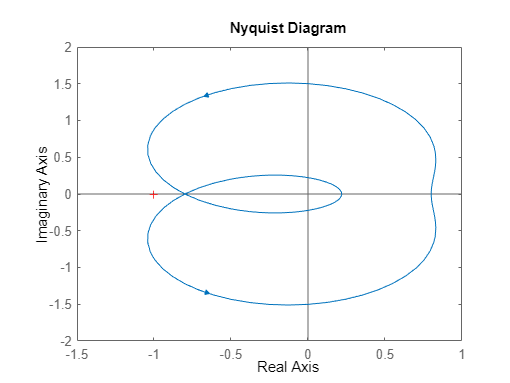

nyquist(Wopen)